# Path Planning for Drone

Move 4 ft x 4 ft drone using RRT Planner

Load map of house 

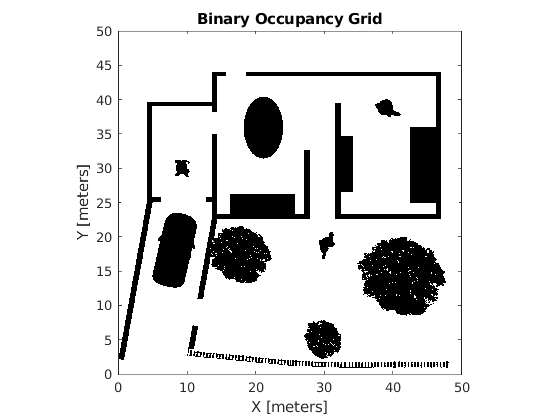

clear all
close all

% load image and create Occupancy map from image
house_occgrid = loadMap('house_map.png', 50);
show(house_occgrid)

Create costmap using vehicleCostmap function from toolbox

costmap = vehicleCostmap(house_occgrid)

costmap =   vehicleCostmap with properties:

        FreeThreshold: 0.2000
    OccupiedThreshold: 0.6500
     CollisionChecker: [1×1 driving.costmap.InflationCollisionChecker]
             CellSize: 0.0333
              MapSize: [1500 1500]
            MapExtent: [0 50 0 50]


Modify dimensions of drone and parameters of collision checker.  Drone is 0.5 m x 0.5 m.  

One circle of radius 0.5 m at the center of the drone will be used to check for collisions.

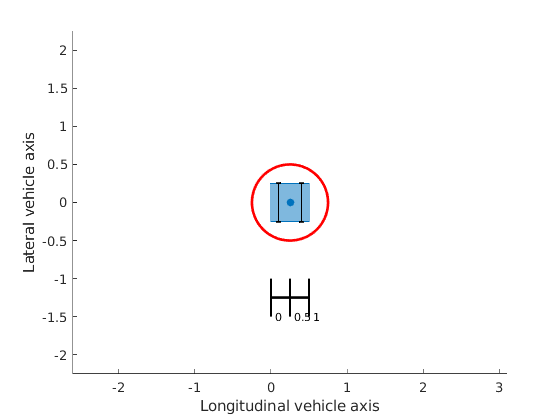


UAVdims = vehicleDimensions(0.5,0.5, 'FrontOverhang',0.1,'RearOverhang',0.1); 
numCircles = 1;
inflationRadius = 0.5;
ccConfig = inflationCollisionChecker(UAVdims, numCircles,'InflationRadius',inflationRadius);
plot(ccConfig)

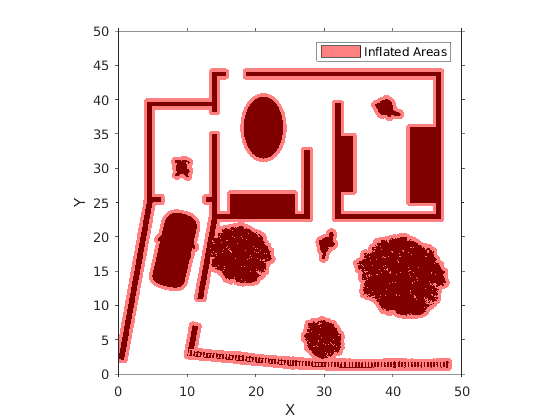


costmap.CollisionChecker = ccConfig;

figure
plot(costmap)

Run the path planner and plot on the map

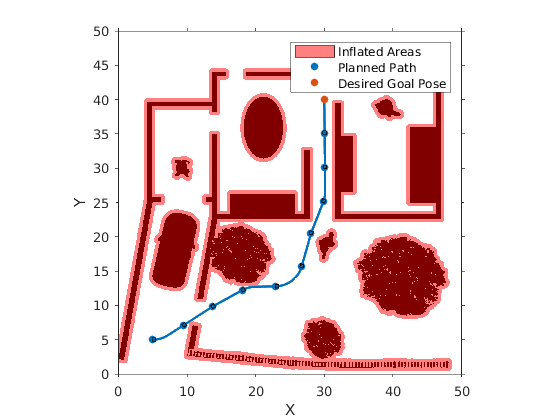

%Set the start and goal states.
start = [5,5,0];
goal = [30,40,90];

planner = pathPlannerRRT(costmap);
refPath = plan(planner,start,goal);

plot(planner)
hold on

UAVsize = 0.5;
inflated_house_occgrid = inflateMap(house_occgrid, UAVsize, 1.25)

inflated_house_occgrid =   binaryOccupancyMap with properties:

   mapLayer Properties
              LayerName: 'binaryLayer'
               DataType: 'logical'
           DefaultValue: 0
    GridLocationInWorld: [0 0]
      GridOriginInLocal: [0 0]
     LocalOriginInWorld: [0 0]
             Resolution: 30
               GridSize: [1500 1500]
           XLocalLimits: [0 50]
           YLocalLimits: [0 50]
           XWorldLimits: [0 50]
           YWorldLimits: [0 50]


[time_traveled, dist_traveled, pthObj, solnInfo] = rrt(inflated_house_occgrid, start, goal)

time_traveled = 0

dist_traveled = 0

pthObj =   navPath with properties:

    StateSpace: [1×1 stateSpaceSE2]
        States: [195×3 double]
     NumStates: 195


solnInfo = struct with fields:
      IsPathFound: 1
         ExitFlag: 1
         NumNodes: 514
    NumIterations: 2027
         TreeData: [1544×3 double]


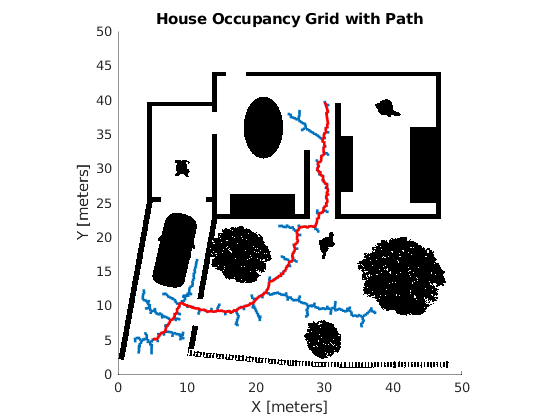

plotSolvedPath(house_occgrid,solnInfo,pthObj,'House Occupancy Grid with Path','/figures/house_path_1.png');